clear all; close all; clc;
% setting the input variables as given in the paper:
T1=62; T2=90; T3=23; T4=30;
A1=28; A2=32; A3 = 28; A4=32;
G1=0.7; G2=0.6; k1= 3.33; k2=3.35; kc=1;

% Forming the Ac, Bc and Hc matrices as given in the paper:
Ac = [-1/T1 0 A3/(A1*T3) 0; 0 -1/T2 0 A4/(A2*T4); 0 0 -1/T3 0; 0 0 0 -1/T4];
Bc = [(G1*k1)/A1 0; 0 (G2*k2)/A2; 0 ((1-G2)*k2)/A3; ((1-G1)*k1)/A4 0];

control_indices = [1,2]; % Indices of the heights being controlled
measured_indices = [3,4];
Cc = zeros(2,4);
Cm = zeros(2,4);
for i = 1:2
    Cm(i,measured_indices(i)) = kc;
    Cc(i,control_indices(i)) = kc;
end      % for case A
Dc = [0 0; 0 0];

% converting continuous to discrete with timestep = 0.1
sysc = ss(Ac,Bc,Cc,Dc);
sysm = ss(Ac,Bc,Cm,Dc);
Ts = 0.1; %time-step
d_sys = c2d(sysc, Ts);
m_sys = c2d(sysm, Ts);
Am_d = d_sys.A;
Bm_d = d_sys.B; % done to define the new discrete A, B, C matrices
Cm_d = d_sys.C;
Cm_dc = m_sys.C;

% Prediction horizon
np = 40;

% control horizon
nc = 20;

% Calculate the matrices 
[phi_phi,phi_F,phi_R,phi, F, BarRs,A_e, B_e,C_e] = mpcgain(Am_d,Bm_d,Cm_d,np,nc);
q = size(Cm_d,1);
[n,m] = size(B_e);
nm = size(Am_d,1);
xm = [12.4; 12.7; 1.8; 1.4];
Xf = zeros(n,1);
N_sim = 500;
r = ones(N_sim,q);
u = zeros(m,1);
y = Cm_d*xm;               
uwt = [5 5];
ysp = [13.4; 13.7];          % case A.1
%ysp = [2.8; 2.4];           % case A.2
%ysp = [13.7; 2.8];          % case A.3      
%ysp = [13.7; 2.4];          % case A.4

Rs = repmat(ysp,np,1);
Rp = zeros(m*nc, m*nc);
Rp(1:m,1:m) = diag(uwt);

x_hat = xm;
p = (10^2)*eye(4); 
Q = 1*eye(4);
R = 1*eye(2);

for i=2:nc
    Rp((i-1)*m+1:i*m, (i-1)*m+1:i*m) = diag(uwt);
end

%Hessian Matrix:
H = phi_phi + Rp;

%Input Constraints:
dUmin = 5*[-1; -1];
dUmax = 5*[1; 1];
Umin = 0*[-1; -1];
Umax = 20*[1; 1];

Ymin = -1*[13.4; 13.7];
Ymax = 1*[13.9; 14];       % for no constraint on output

Ukprev = u;

for kk=1:N_sim
    f = -(phi')*(Rs-F*Xf);
    [M, gamma] = mpc_constraint(phi,F,Xf,Ymin,Ymax,Umin,Umax,dUmin,dUmax,Ukprev,nc,np);
    DeltaU = quadprog(H,f,M,gamma);
    deltau = DeltaU(1:m,1);
    u = u + deltau;
    Ukprev = u;
    u1(:,kk) = u;
    xm_old = xm;
    noise = 0.01*rand(2,1);
    xm_MPC = Am_d*xm+Bm_d*u + ones(4,2)*noise;
    y = Cm_d*xm_MPC+ noise;
    ymeas = Cm_dc*xm_MPC + noise;
    y1(:,kk) = y;
    ymeas1(:,kk) = ymeas;
    
    %prediction step
    x_minus = Am_d*x_hat + Bm_d*u;
    p_minus = Am_d*p*Am_d' + Q;
    
    % calculating Kalman Gain
    K = p_minus*Cm_d'*inv(Cm_d*p_minus*Cm_d' + R);
    
    % updating step
    Z_est = Cm_d*x_minus;
    x_hat = x_minus + K*(y - Z_est);
    p = (eye(4) - K*Cm_d)*p_minus;
    
    %plant simulation
    ycontrol = Cm_d*x_hat;
    
    Xf = [x_hat-xm_old;ycontrol];   % Full state feedback in delta
    xm = x_hat;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

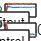


k=0:Ts:(N_sim-1)*Ts;
figure
subplot(211)
plot(k,y1')
xlabel('Time')
legend('Output')
subplot(212)
plot(k,u1)
xlabel('Time')
legend('Control')

%title(num2str(uwt))


## mpcgain

function [phi_phi, phi_F, phi_R, phi, F, BarRs, A_e, B_e, C_e] = mpcgain(Am,Bm,Cm,np,nc);
[q,n1] = size(Cm);
[n1,m] = size(Bm);
A_e = eye(n1+q,n1+q);
A_e(n1+1:n1+q,1:n1) = Cm*Am;
B_e = zeros(n1+q,m);
B_e(1:n1,:)=Bm;                     % n1 = original no. of states
B_e(n1+1:n1+q,:) = Cm*Bm;           % m = no. of in, q = no. of out
C_e = zeros(q,n1+q);
C_e(:,n1+1:n1+q) = eye(q,q);
n = n1+q;
h(1:q,:) = C_e;
F = zeros(q*np,n1+q);
F(1:q,:) = C_e*A_e;
for i=2:np
    h((i-1)*q+1:i*q,:) = h((i-2)*q+1:(i-1)*q,:)*A_e;
    F((i-1)*q+1:i*q,:) = F((i-2)*q+1:(i-1)*q,:)*A_e;
end
v=h*B_e;
phi = zeros(q*np,m*nc);
phi(:,1:m) = v;
for j = 2:nc
    phi(:,(j-1)*m+1:j*m) = [zeros((j-1)*q,m);v(1:q*(np-j+1),1:m)];
end
BarRs = ones(q*np,1);           % setpoint
phi_phi = phi'*phi;
phi_F = phi'*F;
phi_R = phi'*BarRs;
end

%% mpc_constraint

function [M,gamma] = mpc_constraint(phi,F,Xf,Ymin,Ymax,Umin,Umax,dUmin,dUmax,Ukprev,nc,np)
m = size(Ukprev,1);
%q = size(Ymin,1);

C1 = repmat(Ukprev,nc,1);
C2i = repmat(eye(m,m),nc,1);
C2 = zeros(m*nc,m*nc);
C2(:,1:m) = C2i;
UMIN = repmat(Umin,nc,1);
UMAX = repmat(Umax,nc,1);
for i=2:nc
    C2((i-1)*m+1:nc*m,(i-1)*m+1:i*m) = C2i((i-1)*m+1:nc*m,1:m);
end

M1 = [-C2;C2];
N1 = [-UMIN + C1; UMAX - C1];

deltaMin = repmat(dUmin,nc,1);
deltaMax = repmat(dUmax,nc,1);

M2 = [-eye(m*nc,m*nc);eye(m*nc,m*nc)];
N2 = [-deltaMin;deltaMax];

M3 = [-phi ; phi];
N3 = [(-Ymin'*ones(2,2*np))' + F*Xf ; (Ymax'*ones(2,2*np))' - F*Xf];

M = [M1;M2;M3];
gamma = [N1;N2;N3];
end